%clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
start=0;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none','FiniteDifferenceType','central');
    
ARTEMIS=ARTEMIS_road;

%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici

SOC=0.55*ones(1,N);
u_n=1*ones(1,N);
N_rounds=2;
N_it=1000;
u=zeros(1,N_it*N_rounds);
tic
for k=1:N_rounds
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
        speed=ARTEMIS(1,start+j:start+N-1+j);
        acceleration=ARTEMIS(2,start+j:start+N-1+j);
        gear=ARTEMIS(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
        FullStateUpdate=@(u)full_horizon(u,SOC(end),StateUpdate);
        nonlinconstr_h=@(u)nonlinconstr(u,SOC(end),StateUpdate);
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        %tic
        [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,[u_n(2:end),mean(u_n)],[],[],[],[],...
            -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
        %toc
        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            j
            exitf(j)
        end
    
        if rem(j,N_it/10)==0
            fprintf("Siamo al: %f percento dell'iterazione %d \n Ci ha messo %f \n",j/(N_it)*100,k,toc)
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Siamo al: 10.000000 percento dell'iterazione 1 
 Ci ha messo 9.566301 


j = 104

ans = 0

Siamo al: 20.000000 percento dell'iterazione 1 
 Ci ha messo 9.650376 
Siamo al: 30.000000 percento dell'iterazione 1 
 Ci ha messo 10.080649 
Siamo al: 40.000000 percento dell'iterazione 1 
 Ci ha messo 20.293053 


j = 441

ans = -2

j = 442

ans = -2

j = 443

ans = -2

j = 444

ans = -2

j = 445

ans = -2

j = 446

ans = -2

j = 447

ans = -2

j = 448

ans = -2

j = 449

ans = -2

j = 450

ans = -2

j = 451

ans = -2

j = 462

ans = -2

j = 463

ans = -2

j = 464

ans = -2

j = 465

ans = -2

j = 466

ans = -2

j = 467

ans = -2

j = 468

ans = -2

j = 469

ans = -2

j = 470

ans = -2

j = 471

ans = -2

j = 472

ans = -2

j = 473

ans = -2

j = 474

ans = -2

j = 475

ans = -2

j = 476

ans = -2

j = 477

ans = -2

j = 478

ans = -2

j = 479

ans = -2

j = 480

ans = -2

j = 481

ans = -2

j = 482

ans = -2

Siamo al: 50.000000 percento dell'iterazione 1 
 Ci ha messo 13.608413 


j = 527

ans = -2

j = 528

ans = -2

j = 529

ans = -2

j = 530

ans = -2

j = 531

ans = -2

j = 532

ans = -2

j = 533

ans = -2

j = 534

ans = -2

j = 535

ans = -2

j = 536

ans = -2

Siamo al: 60.000000 percento dell'iterazione 1 
 Ci ha messo 9.084741 
Siamo al: 70.000000 percento dell'iterazione 1 
 Ci ha messo 3.083877 
Siamo al: 80.000000 percento dell'iterazione 1 
 Ci ha messo 8.016854 
Siamo al: 90.000000 percento dell'iterazione 1 
 Ci ha messo 3.939736 


j = 929

ans = 0

j = 931

ans = 0

toc

Elapsed time is 12.022901 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];
acceleration=[];
gear=[];
for i=1:k
    speed=[speed,ARTEMIS(1,start+1:start+N+j)];
    acceleration=[acceleration,ARTEMIS(2,start+1:start+N+j)];
    gear=[gear,ARTEMIS(3,start+1:start+N+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,SOC,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,0.55,StateUpdate);
tot_c=sum(sum(c<=0))/(4*length(c))

tot_c = 0.9990

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)/length(ceq)

tot_ceq = 0.9980

tot_mf=sum(mf)

tot_mf = 0.1124

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = -0.0027

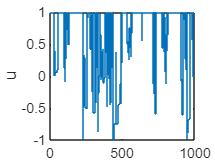


stairs(u)
ylabel('u')

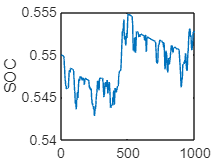

plot(SOC)
ylabel('SOC')

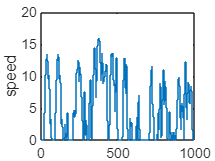

stairs(speed)
ylabel('speed')

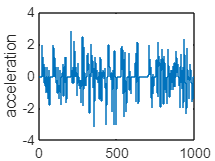

stairs(acceleration)
ylabel('acceleration')

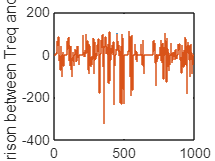

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')